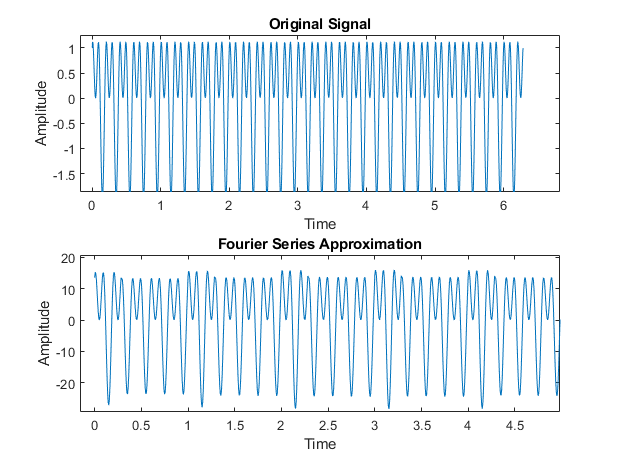

% Define the signal
t = linspace(0, 2*pi, 1000); % time vector
f = sin(2*pi*5*t) + cos(2*pi*10*t); % signal with two frequencies

% Compute the Fourier series coefficients
N = length(t);
a0 = 1/N * sum(f);
an = zeros(1, N);
bn = zeros(1, N);
for n = 1:N
    an(n) = 2/N * sum(f .* cos(2*pi*n*t));
    bn(n) = 2/N * sum(f .* sin(2*pi*n*t));
end

% Compute the Fourier series approximation
f_approx = a0/2;
for n = 1:N
    f_approx = f_approx + an(n)*cos(2*pi*n*t) + bn(n)*sin(2*pi*n*t);
end

% Plot the original signal and its Fourier series approximation
subplot(2,1,1);
plot(t, f);
title('Original Signal');
xlabel('Time');
ylabel('Amplitude');
subplot(2,1,2);
plot(t, f_approx);
title('Fourier Series Approximation');
xlabel('Time');
ylabel('Amplitude');



a0 = 1/N * sum(f);
an = 2/N * sum(f .* cos(2*pi*n*t));
bn = 2/N * sum(f .* sin(2*pi*n*t));


f_approx = a0/2 + sum(an.*cos(2*pi*n*t) + bn.*sin(2*pi*n*t));
